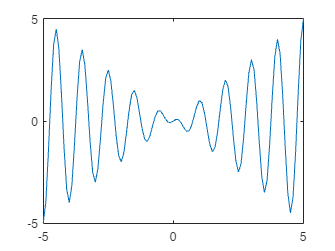

% f(t) = tcos(2pi*t), -5<= t <= 5

t= -5:0.1:5; % Time interval entre cada sample é 0.1
% Tambem se pode escrever assim: t = -5:5 mas aí o matlab assume um sample
% period de 1.
f = t.*cos(2*pi*t);
plot(t,f)

%para fazer funcoes, mas para isso precisamos de de outro file de script.
%mas vou deixar aqui o script


%function [sm, prod] = oper(A,B)
%sm = A+B          -> soma
%prod = A*B         -> produto
%end
%basta passar os valores de A e B
%Neste caso esta funcao só serve para multplicar duas matrizes

 %umas operacoes uteis:
a = [4,2,7,0,6];
s = sum(a) % soma normal

s = 19

c = cumsum(a) % soma comulativa

c =      4     6    13    13    19


p = prod(a) %produto de todos os elementos

p = 0

d = diff(a) %diferença de dois elementos consecutivos ou seja: 2-4, 7-2, 0-7, 6-0;

d =     -2     5    -7     6


[m,i] = max(a) %o maior valor = m, o seu index = i

m = 7

i = 3

[mm,ii] = min(a) %mesma coisa que o de cima mas para o meno valor

mm = 0

ii = 4

sort(a) %sort em ascending order

ans =      0     2     4     6     7


sort(a,'descend') %mesma coisa a descer

ans =      7     6     4     2     0


%Alguns tipos de matrizes:

ones(2,3) %matriz de 1's 2x3

ans =      1     1     1
     1     1     1



zeros(1,4)%mesma coisa que em cima mas 1x4 e de zeros

ans =      0     0     0     0



rand(3) %random

ans =     0.6991    0.5472    0.2575
    0.8909    0.1386    0.8407
    0.9593    0.1493    0.2543



eye(4,2) %1's na diagonal principal resto 0's

ans =      1     0
     0     1
     0     0
     0     0



eye(4) %equivalente a fazer eye(4,4)

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1



magic(3) %esta matriz é gerada e a soma de todas as colunas e linhas é a mesma.

ans =      8     1     6
     3     5     7
     4     9     2


%Plotting signals

%plot the function y(x) = x^2, -2<=x<=2

x = -2:0.1:2;
yx =x.^2;
length(yx)

ans = 41

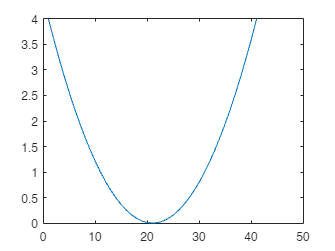

plot(yx)

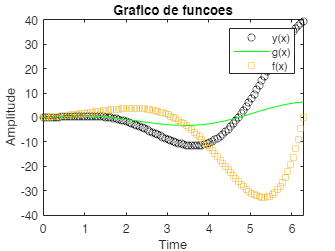

%Fazer vários plot numa figura 

%plot y(x) = x^2*cos(x),  g(x) = x*cos(x), and f = 2^x * sin(x), 0<=x<=2pi


x = 0:pi/50:2*pi;

y = (x.^2).*cos(x);
g = x.*cos(x);
f = (2.^x).*sin(x);

plot(x,y,'Ko',x,g,'G',x,f,'s') %as strings ai no meio sao so maneiras diferentes de representar a funcao, nao deve ser preciso saber todas de cabeça
xlabel('Time')
ylabel('Amplitude')
title('Grafico de funcoes')
legend('y(x)','g(x)','f(x)')